# Create Transmission Energy Charting for a Tractor

This example shows how to compute energy input, output, losses for different components of a tractor. This example also represents the energy flow of a tractor.

Copyright 2024 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('TractorModelOverview.html')).

## Energy Flow Diagram

In tractors, the power from engine fuel consumption is wasted during the flow of energy to the wheels. Typically, the energy loss occurs primarily in the engine and transmission. Other factors such as tire-soil interaction, implement operation, and vibration of the body or energy absorption by the suspension also contribute to the net loss of energy.

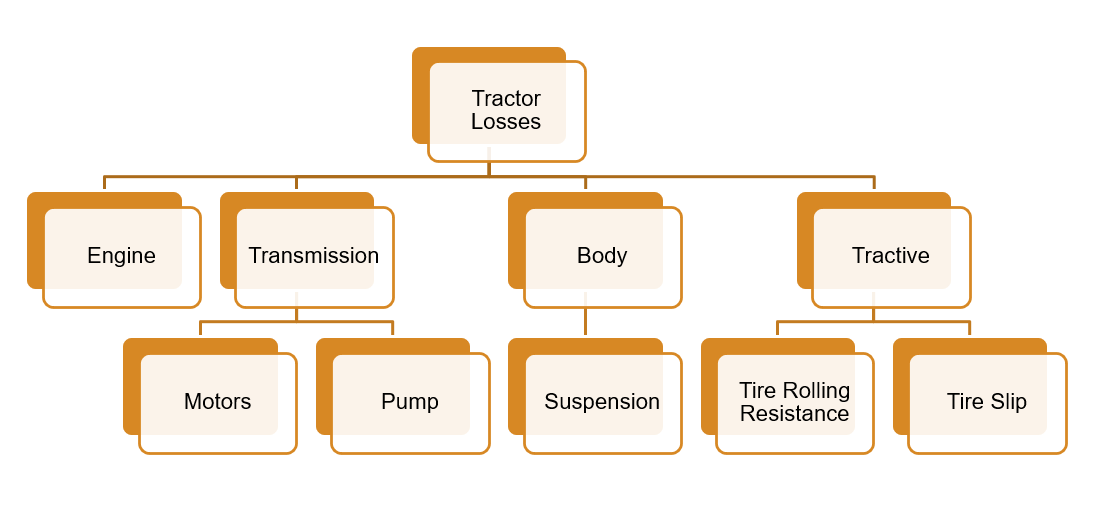

The overall efficiency for a tractor is defined by the below relation.

***Overall Efficiency = Engine Efficiency * Transmission Efficiency * Tractive Efficiency***

The equation shows that it is important to quantify and minimize engine losses, transmission losses, and tractive losses for an energy efficient tractor operation. This workflow focusses on evaluating the input energy, output energy, and lossses encountered in the transmission. You can use this workflow to estimate the transmission losses and graphically visualize the losses through an energy flow diagram. You can also use the results of this workflow to perform a design trade-off study for the transmission.

## Compute Energy Inflow and Outflow

Open the model. 

modelName = 'TractorEnergyComputation';
open_system(modelName)

You can calculate the energy consumed by each component of the tractor in the Energy Calculations subsystem. To view the energy calculations for various components of the tractor, look inside the subsystem.

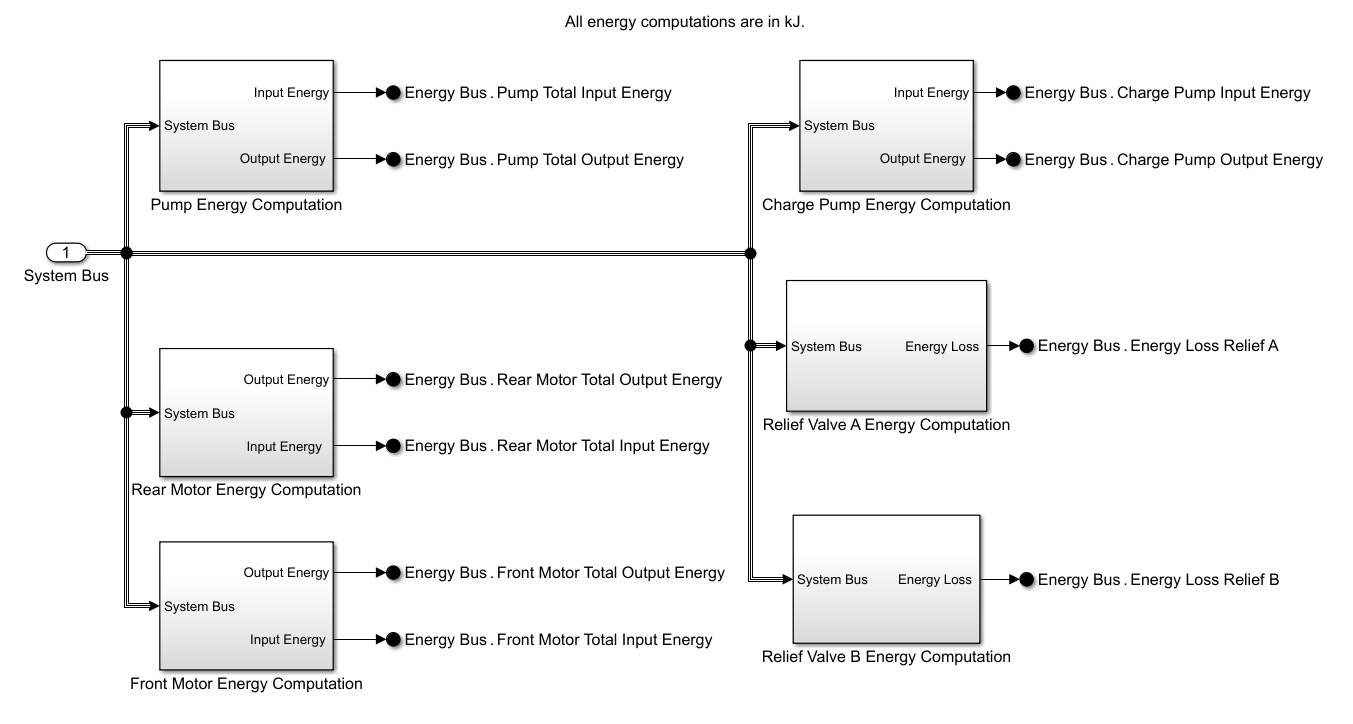

The subsystem has energy calculations for the front motor, rear motor, pump and relief valves. You can view the energy calculations of each of these components by looking inside each of the subsystems. Each of these individual component subsystems have calculations for energy input and energy output. For example, to view the detailed energy input calculations for the front motor, look inside Energy Calculations > Front Motor Energy Computation > Motor Input Energy Computation.

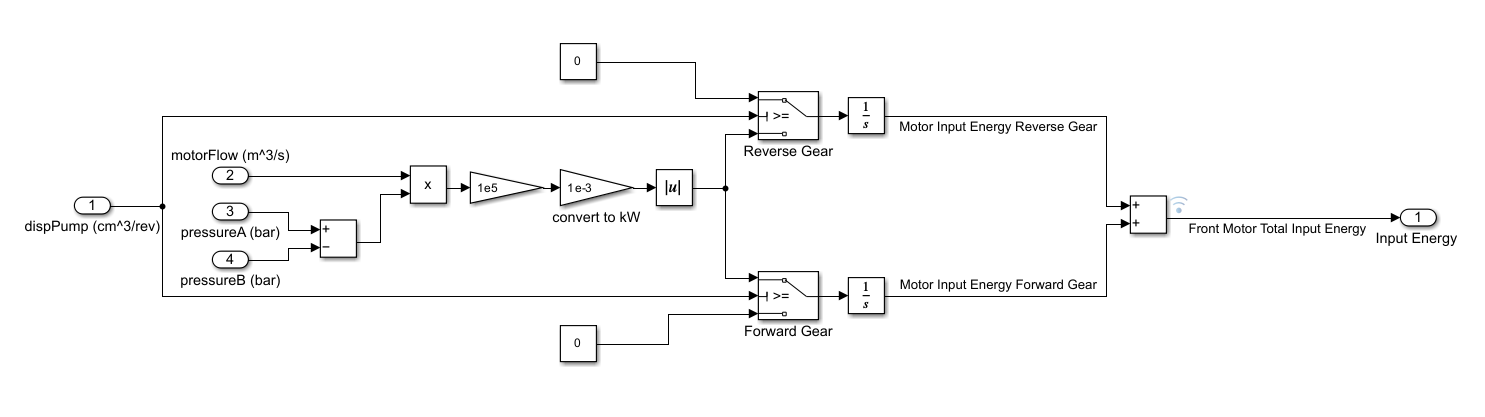

## Visualize Energy Inflow and Outflow

Define a Simulink.SimulationInput object. Run the model.

simIn = Simulink.SimulationInput(modelName);
SimT = 4000;
simIn = setModelParameter(simIn,"StopTime",string(SimT)); % Set stop time for simulation
simOut = sim(simIn);

You can visualize the inflow and outflow of energy in the Transmission Energy Chart Dashboard subsystem. To view the energy computations for various components of the tractor, look inside the subsystem. The blue lines represent the energy flow in the forward gears of tractor operation, while the yellow lines represent the energy flow in the reverse gear. Similarly, the numbers inside the blue rectangles show the energy computation in kJ for forward gears, while the numbers inside the yellow rectangles show the energy computation in kJ for the reverse gear. The pump displacement is positive for the forward gears and negative for the reverse gear. You can compute the available, useful, recirculated, wasted energies as well as the efficiency of the components from the energy flow chart.

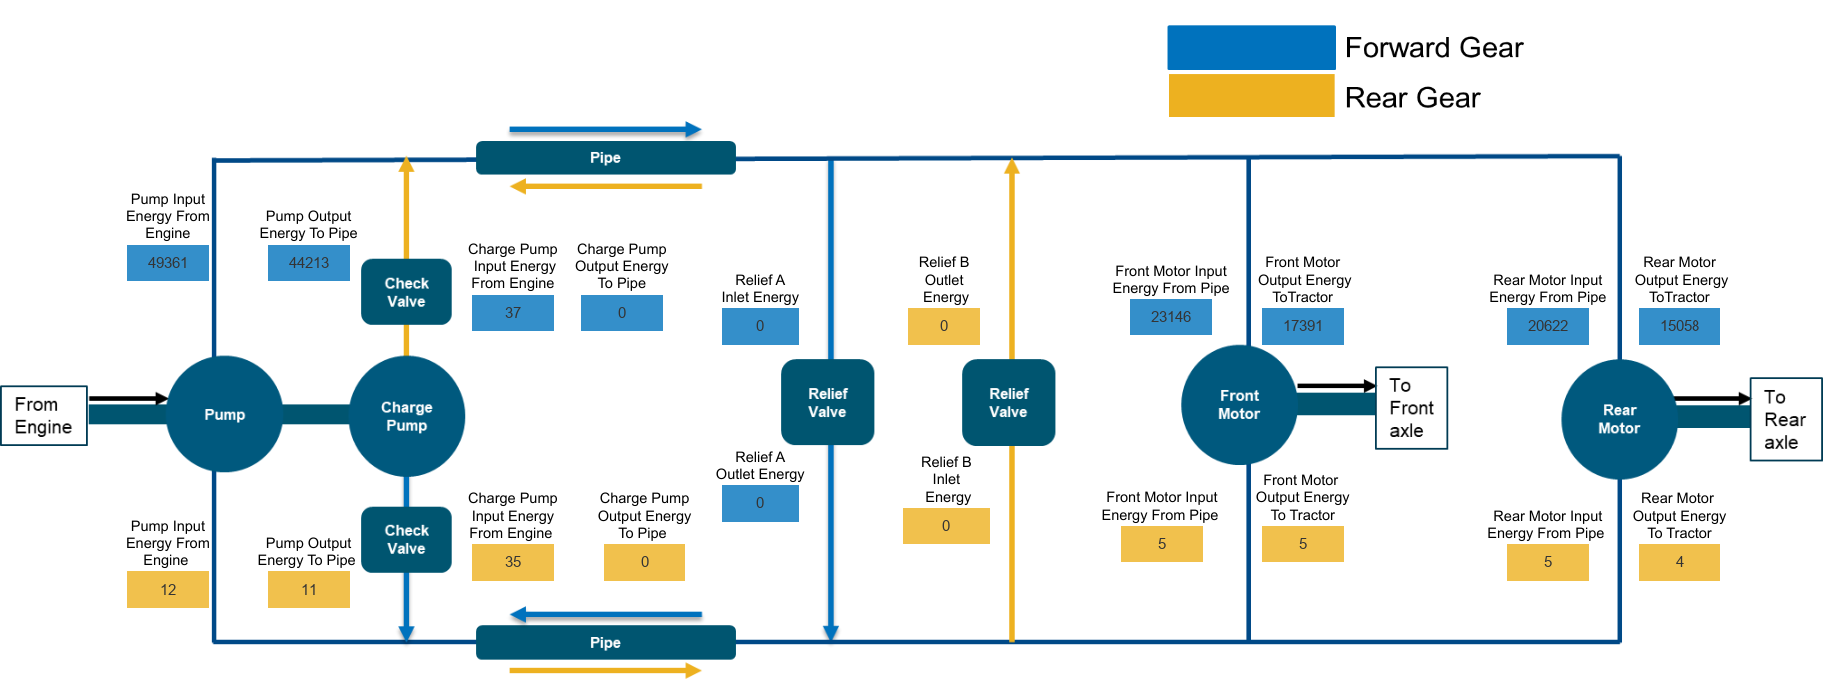

## Plot Sankey Diagram

Plot the Sankey Diagram using the total input energy and the losses for various components. You can run [`computeLosses`](matlab:open('../../Scripts/computeLosses.m')) function to calculate the energy loss of front motor, rear motor, pump, charge pump, and other auxiliary components, such as relief valves, using the simulation output data. You can also calculate the total input energy to the system or the total input energy from engine.

plotEnergySankey(simOut.logsoutTractorEnergyComputation)

Calculating the energy losses for various components of tractor


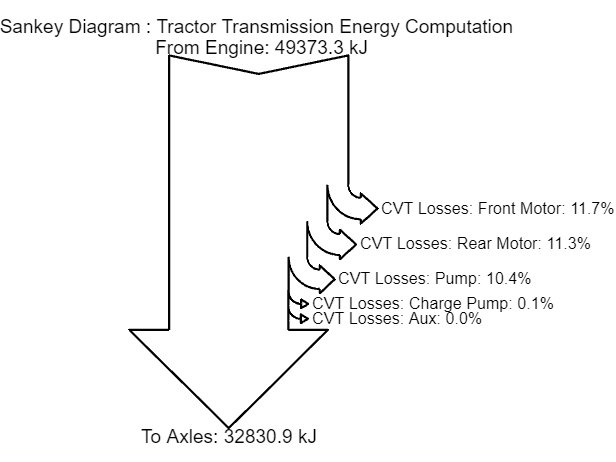

xlim([-0.6 2.15])
ylim([-2.2 0.3])

## Conclusion

From the Sankey diagram, you can infer that the most of the energy from engine is lost in the hydraulic pump. The secondary contributing factors are the losses encounterd in the front and rear motors. Losses in relief valves are insignificant. 